Example script for the use of Matlab - EIOT using data from:

    Dyrby, M., Engelsen, S.B., Ngaard, L., Bruhn, M. and Lundsberg-Nielsen, L., 2002. 

    Chemometric quantitation of the active substance (containing C? N) in a pharmaceutical 

    tablet using near-infrared (NIR) transmittance and NIR FT-Raman spectra. 

    Applied Spectroscopy, 56(5), pp.579-585.

    Raw data available from: http://www.models.life.ku.dk/Tablets

Needs eiot toolbox for MATLAB (mEIOT)

    https://github.com/salvadorgarciamunoz/eiot

%}

%

% LOAD THE DATA, SEPARATE IT INTO CALIBRATION AND VALUDATION SETS, 

% PREPROCESS DATA AND DO SOME PLOTS

%

% spectra_cal_savgol/spectra_val_savgol : Spectra pre-processed by 1st derivative 

%                                         Savitzky Golay with 11 points

%                                         (5 points per side)and 2nd

%                                          order polynomial

%                                         

% Ck_cal/Ck_val                         : Mass fraction for the 2 species

%

% dose_source_cal/dose_source_val       : Prior Knowleged on dose and

%                                         source of the tablet (lab,pilot,commercial)

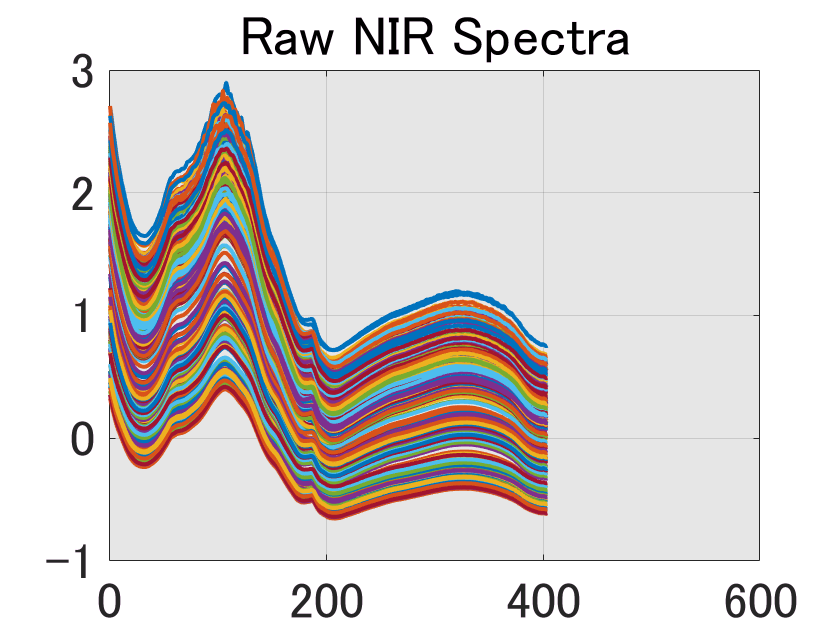

load NIR_EIOT_Dyrby_et_al.MAT
figure,plot(spectra'),title('Raw NIR Spectra'),set(gcf,'Name','Complete Set Raw Spectra')

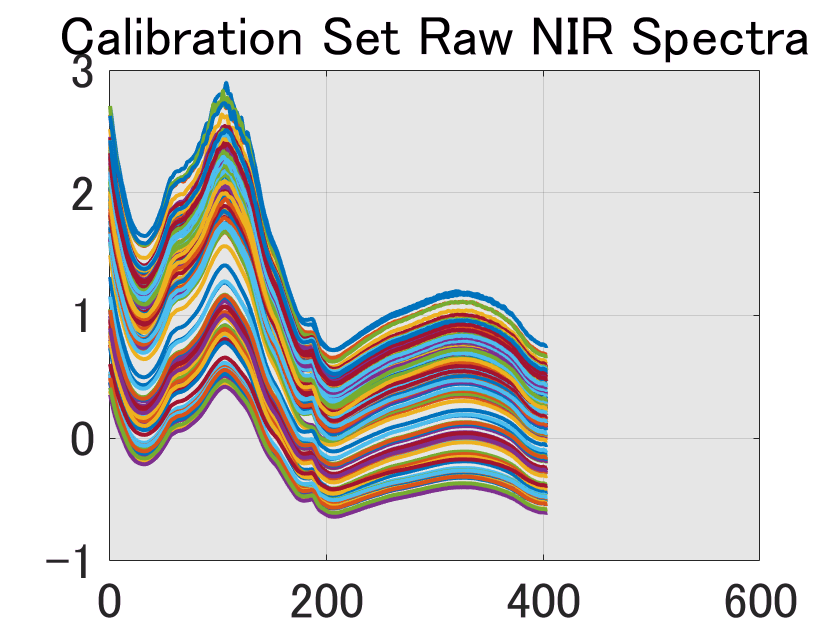

spectra_cal     = spectra     (1:2:end,:);
Ck_cal          = Ck          (1:2:end,:);
dose_source_cal = dose_source (1:2:end,:);
spectra_val     = spectra     (2:2:end,:);
Ck_val          = Ck          (2:2:end,:);
dose_source_val = dose_source (2:2:end,:);
figure,plot(spectra_cal'),title('Calibration Set Raw NIR Spectra'),set(gcf,'Name','Calibration Set Raw Spectra')

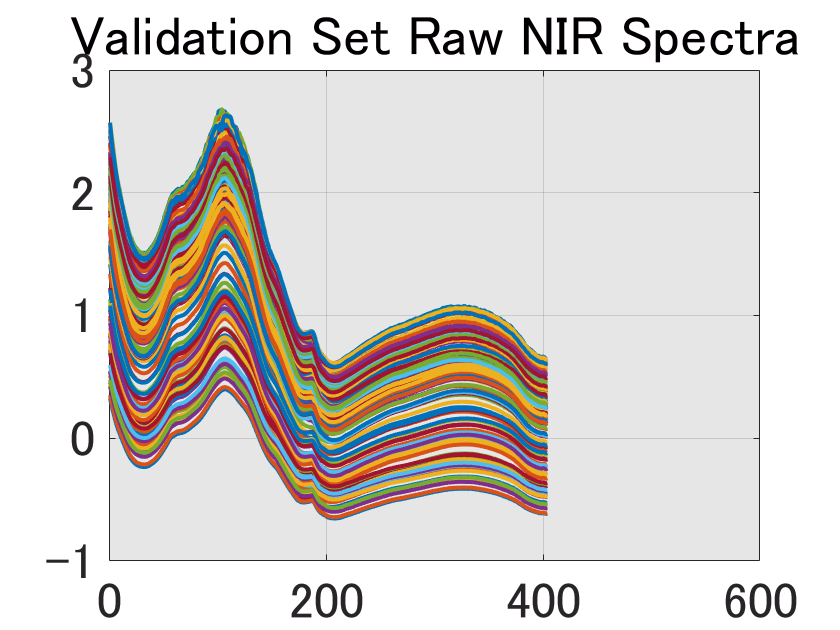

figure,plot(spectra_val'),title('Validation Set Raw NIR Spectra'),set(gcf,'Name','Validation Set Raw Spectra')

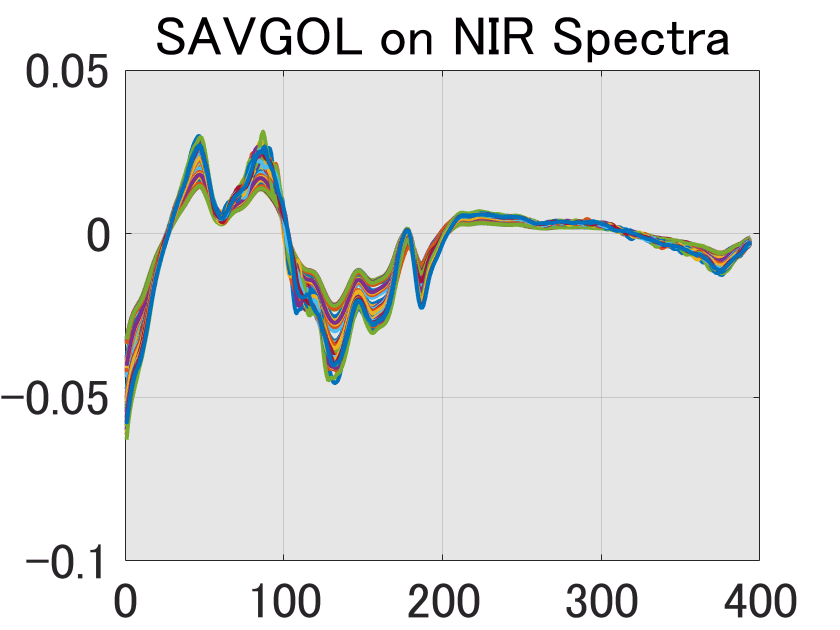

[spectra_cal_savgol,M] = eiot_savgol(spectra_cal, 5, 2, 1);
[spectra_val_savgol,M] = eiot_savgol(spectra_val, 5, 2, 1);
figure,plot(spectra_cal_savgol');title('SAVGOL on NIR Spectra'),set(gcf,'Name','Calibration Set SAVGOL Spectra')

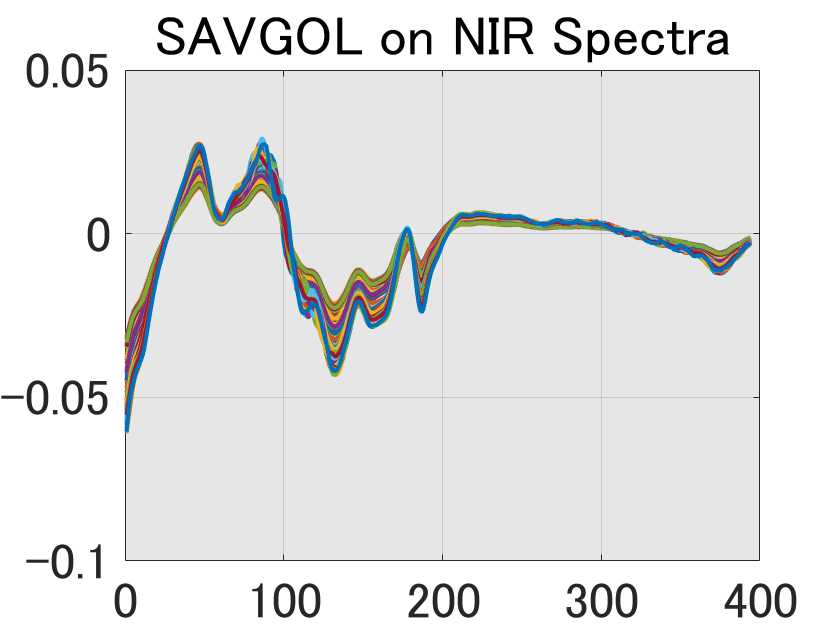

figure,plot(spectra_val_savgol');title('SAVGOL on NIR Spectra'),set(gcf,'Name','Validation  Set SAVGOL Spectra')

%

% BUILD AN UNSUPERVISED EIOT OBJECT WITH ZERO NON-CHEMICAL INTERFERENCES 

% AND PLOT THE LAMBDA VALUES FOR THE CHEMICAL ERROR

%

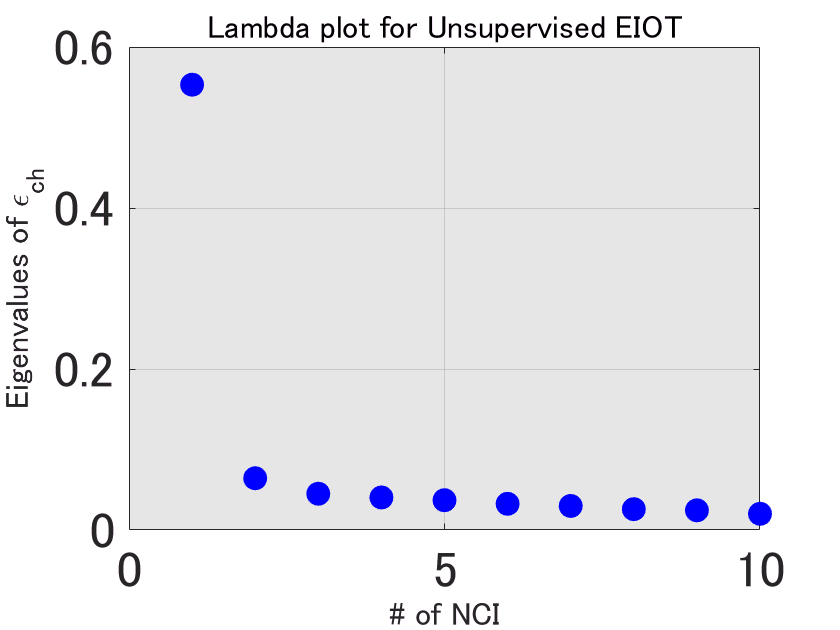


eiot_obj=eiot_build(spectra_cal_savgol,Ck_cal,0);
figure,
plot(eiot_obj.lambdas(1:10),'ob','MarkerFaceColor','b','MarkerSize',10)
title('Lambda plot for Unsupervised EIOT','FontSize',16)
xlabel('# of NCI','FontSize',16)
ylabel('Eigenvalues of \epsilon_{ch}','FontSize',16)

%

% BUILD AN UNSUPERVISED EIOT OBJECT WITH INCREASING NUMBER OF NON-CHEMICAL 

% INTERFERENCES AND PLOT THE RMSE OF THE VALIDATION SET VS THE #NCI

% IN THE EIOT OBJECT

%

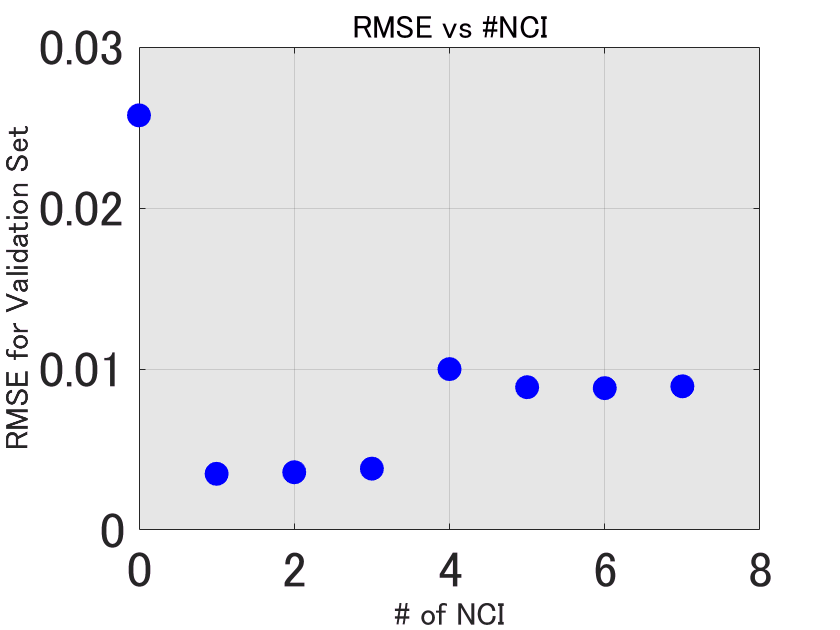

rmse_vs_nci = [];
for nci = 0:7
    eiot_obj             = eiot_build(spectra_cal_savgol,Ck_cal,nci);
    [r_hat, ri_hat, ssr] = eiot_calc(spectra_val_savgol,eiot_obj);
    error = Ck_val(:,1) - r_hat(:,1);
    rmse_ = sqrt(mean(error.^2));
    rmse_vs_nci=[rmse_vs_nci;rmse_];
end
figure,
plot([0:7],rmse_vs_nci,'ob','MarkerFaceColor','b','MarkerSize',10)
title('RMSE vs #NCI','FontSize',16)
xlabel('# of NCI','FontSize',16)
ylabel('RMSE for Validation Set','FontSize',16)

%

% BUILD AN SUPERVISED EIOT OBJECT WITH ZERO NON-CHEMICAL INTERFERENCES 

% AND PLOT THE LAMBDA VALUES FOR THE CHEMICAL ERROR

%                                            

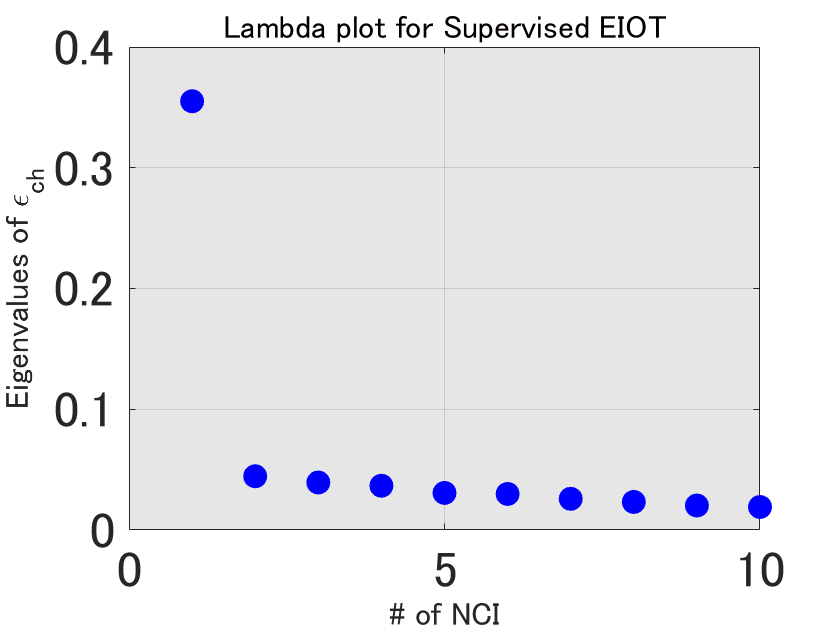

eiot_obj_sup=eiot_build(spectra_cal_savgol,Ck_cal,0,dose_source_cal);
figure,
plot(eiot_obj_sup.lambdas(1:10),'ob','MarkerFaceColor','b','MarkerSize',10)
title('Lambda plot for Supervised EIOT','FontSize',16)
xlabel('# of NCI','FontSize',16)
ylabel('Eigenvalues of \epsilon_{ch}','FontSize',16)

%

% BUILD AN SUPERVISED EIOT OBJECT WITH INCREASING NUMBER OF NON-CHEMICAL 

% INTERFERENCES AND PLOT THE RMSE OF THE VALIDATION SET VS THE #NCI

% IN THE EIOT OBJECT USING ACTIVE AND PASSIVE SUPERVISION

%

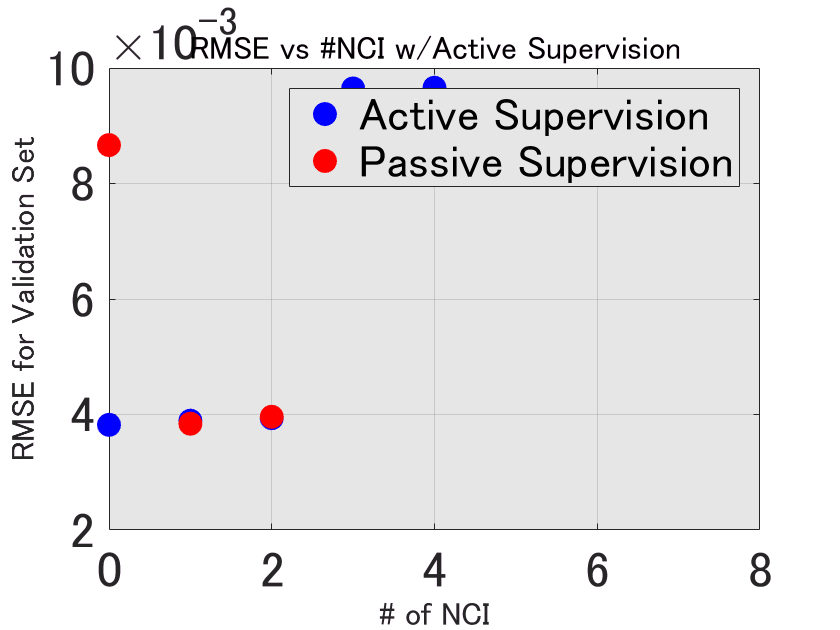

rmse_vs_nci_ps = [];
rmse_vs_nci_as = [];
for nci = 0:7
    eiot_obj_sup = eiot_build(spectra_cal_savgol,Ck_cal,nci,dose_source_cal);
    [r_hat_ps, ri_hat, ssr] = eiot_calc(spectra_val_savgol,eiot_obj_sup);
    [r_hat_as, ri_hat, ssr] = eiot_calc(spectra_val_savgol,eiot_obj_sup,0,dose_source_val);
    error_as = Ck_val(:,1) - r_hat_as(:,1);
    error_ps = Ck_val(:,1) - r_hat_ps(:,1);
    rmse_as = sqrt(mean(error_as.^2));
    rmse_ps = sqrt(mean(error_ps.^2));
    rmse_vs_nci_as=[rmse_vs_nci_as;rmse_as];
    rmse_vs_nci_ps=[rmse_vs_nci_ps;rmse_ps];
end
figure,
plot([0:7],rmse_vs_nci_ps,'ob','MarkerFaceColor','b','MarkerSize',10)
title('RMSE vs #NCI w/Passive Supervision','FontSize',16)
xlabel('# of NCI','FontSize',16)
ylabel('RMSE for Validation Set','FontSize',16)
hold on
plot([0:7],rmse_vs_nci_as,'or','MarkerFaceColor','r','MarkerSize',10)
title('RMSE vs #NCI w/Active Supervision','FontSize',16)
xlabel('# of NCI','FontSize',16)
ylabel('RMSE for Validation Set','FontSize',16)
legend({'Active Supervision','Passive Supervision'})

%

% BUILD UNSUPERVISED EIOT OBJECT WITH 1 NCI

%

eiot_obj=eiot_build(spectra_cal_savgol,Ck_cal,1);

%

% PREDICT VALIDATION DATA WITH UNSUPERVISED MODEL

%

[r_hat_unsup, ri_hat_unsup, ssr_unsup] ...
    = eiot_calc(spectra_val_savgol,eiot_obj);

%

% BUILD SUPERVISED EIOT OBJECT WITH 1 NCI

%

eiot_obj_sup=eiot_build(spectra_cal_savgol,Ck_cal,1,dose_source_cal);

%

% PREDICT VALIDATION DATA WITH SUPERVISED MODEL IN PASSIVE SUPERVISION MODE

%

[r_hat_ps, ri_hat_ps, ssr_ps] = eiot_calc(spectra_val_savgol,eiot_obj_sup);

%

% PREDICT VALIDATION DATA WITH SUPERVISED MODEL IN ACTIVE SUPERVISION MODE

%

[r_hat_as, ri_hat_as, ssr_as] = ...
    eiot_calc(spectra_val_savgol,eiot_obj_sup,0,dose_source_val);

%

%PLOT PRED VS OBSERVED FOR ALL 3 CASES

%

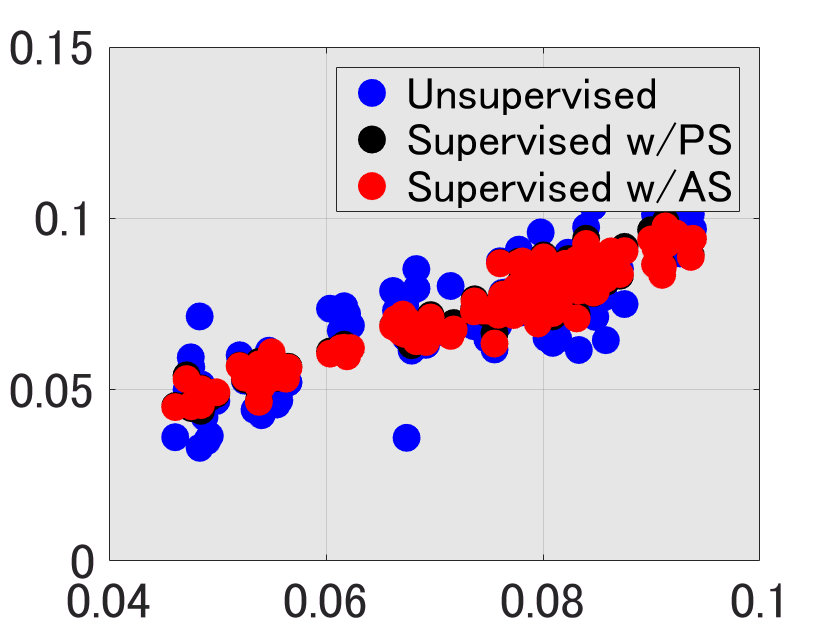

figure,
plot(Ck_val(:,1),r_hat_unsup(:,1),'ob','MarkerFaceColor','b'),hold on
plot(Ck_val(:,1),r_hat_ps(:,1),'ok','MarkerFaceColor','k')
plot(Ck_val(:,1),r_hat_as(:,1),'or','MarkerFaceColor','r')
legend({'Unsupervised';'Supervised w/PS';'Supervised w/AS'})

%Calculate RMSE for all thre cases

error_unsup = Ck_val(:,1) - r_hat_unsup(:,1);
error_as = Ck_val(:,1) - r_hat_as(:,1);
error_ps = Ck_val(:,1) - r_hat_ps(:,1);
rmse_unsup = sqrt(mean(error_unsup.^2));
rmse_as = sqrt(mean(error_as.^2));
rmse_ps = sqrt(mean(error_ps.^2));
fprintf(['RMSE Unsupervised   : ',num2str(rmse_unsup),'\n'])

RMSE Unsupervised   : 0.0089243


fprintf(['RMSE Supervised wPS : ',num2str(rmse_ps),'\n'])

RMSE Supervised wPS : 0.0038931


fprintf(['RMSE Supervised wAS : ',num2str(rmse_as),'\n'])

RMSE Supervised wAS : 0.0038407
